Fundamentos de control                                                                                                                                                                                                       

# Descripción externa e interna

## Equivalencia entre descripciones

En los dos cuadernos anteriores hemos trabajado con la descripción externa (función de transferencia) e interna (espacio de estados) de sistemas. Tratándose de distintas representaciones de un mismo sistema, es posible establecer relaciones entre ellas.

## 1. Paso a descripción externa

Dado un sistema en descripción interna, es posible obtener su equivalente en descripción externa aplicando la transformada de Laplace a la ecuación de estado, con condiciones iniciales nulas. De este modo, se llega a la siguiente igualdad:


$$G\left(s\right)={C\left(\mathrm{sI}-A\right)}^{-1} B+D$$


**Tarea 1:** Obtener la función de transferencia $G\left(s\right)$del circuito LRC del cuaderno anterior expresado en espacio de estados, definido en la siguiente celda de código, empleando la equivalencia anterior.

% Constantes del sistema
L = 0.5; R = 10; C= 0.001;
% Matrices del espacio de estados
A = [0 1; -1/(L*C) -R/L]; % matriz dinámica
B = [0; 1/(L*C)];         % matriz de control
C = [1 0];                % matriz de salida
D = [0];                  % matriz de influencia directa
I = eye(2);

% Tu código aquí
s = tf('s'); 
G = C*((s*I-A)^-1)*B+D

G =
 
        2000
  -----------------
  s^2 + 20 s + 2000
 
Continuous-time transfer function.
Model Properties


`Resultado esperado:`

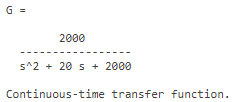

## `2. Paso a descripción externa`

El paso de descripción interna a externa no es único, ya que existen infinitas posibilidades para realizarlo. Por ello, se suele recurrir a formas canónicas, que fijan un procedimiento para dicha conversión y presentan ventajas de cara a estudiar la estabilidad del sistema, controlabilidad, observabilidad, etc. Ejemplo de estas formas canónicas son la de Jordan, la de controlabilidad, o la de observabilidad. 

## `3. Equivalencia entre descripciones en MATLAB`

MATLAB nos permite convertir un modelo en descripción interna a su equivalente en descripción externa, esto es, obtener su función de transferencia. Esto se puede hacer simplemente llamando a la función `tf` e introduciendo el modelo del sistema en descripción interna como argumento. Su sintaxis sería:

**Tarea 2:** Obtener la función de transferencia del circuito LRC, empleando primero las matrices A, B, C y D para definir su representación en espacio de estados, y una vez en descripción externa, utilizar el comando `tf` para obtener su función de transferencia. Comprueba que obtienes el mismo resultado que usando la equivalencia de la sección 1 (Tarea 1).

% Tu código aquí 
L = 0.5; 
R = 10; 
C= 0.001;
% Matrices del espacio de estados
A = [0 1; -1/(L*C) -R/L]; % matriz dinámica
B = [0; 1/(L*C)];         % matriz de control
C = [1 0];                % matriz de salida
D = [0];                  % matriz de influencia directa

%Usamos el comando ss para modelar su representación en espacio de estados 
LRC = ss(A,B,C,D)

LRC =
 
  A = 
          x1     x2
   x1      0      1
   x2  -2000    -20
 
  B = 
         u1
   x1     0
   x2  2000
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties


G2 = tf(G)

G2 =
 
        2000
  -----------------
  s^2 + 20 s + 2000
 
Continuous-time transfer function.
Model Properties


G2 = tf(LRC)

G2 =
 
        2000
  -----------------
  s^2 + 20 s + 2000
 
Continuous-time transfer function.
Model Properties


¡OJO! La operación inversa, pasar de descripción externa a interna empleando el comando `ss`, puede no dar siempre el mismo resultado, ya que como sabemos la descripción externa de un sistema no es única: puede haber múltiples descripciones en función de las variables de estado escogidas, y MATLAB tiene libertad de elección. Aún así, el modelo obtenido sigue siendo válido. Ejemplo:

circuito_bis = ss(G)

circuito_bis =
 
  A = 
          x1     x2
   x1    -20  -62.5
   x2     32      0
 
  B = 
       u1
   x1   8
   x2   0
 
  C = 
          x1     x2
   y1      0  7.812
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Mo

Podemos comprobar como el resultado es una descripción interna distinta a la anterior, pero igualmente válida, ya que se diferencian en las variables de estado empleadas para caracterizar la evolución del sistema. 